# Exploring unreported cases

## Load Data


%load_data_county;
load_data_us;
%load_data_global;

## Filter data to select regions

Here we choose, which regions we are interested in. Regions that do not show a stable pattern (for example, Washington) should not be chosen

% sel_idx = startsWith(countries, 'Los Angeles') | startsWith(countries, 'New York City');
% sel_idx = startsWith(countries, 'California')| startsWith(countries, 'New York') | startsWith(countries, 'Texas') | startsWith(countries, 'Washington');
% sel_idx = sel_idx | startsWith(countries, 'New Jersey')| startsWith(countries, 'Illinois') | startsWith(countries, 'Massachusetts');
% sel_idx = sel_idx | strcmpi(countries, 'US');
sel_idx = data_4(:, 75) > 50;
data_4_s1 = data_4(sel_idx, :);


popu = popu(sel_idx);
countries = countries(sel_idx);
passengerFlow = passengerFlow(sel_idx, sel_idx);

## Prepare training

data_4_s = [data_4_s1(:, 1) cumsum(movmean(diff(data_4_s1')', 7, 2), 2)];

%sd_start = T_tr
start_time = 70;
T_tr = start_time;
T_val = 130 - T_tr;

alpha_start = 5;
horizon = 100;


## Plot a region's data

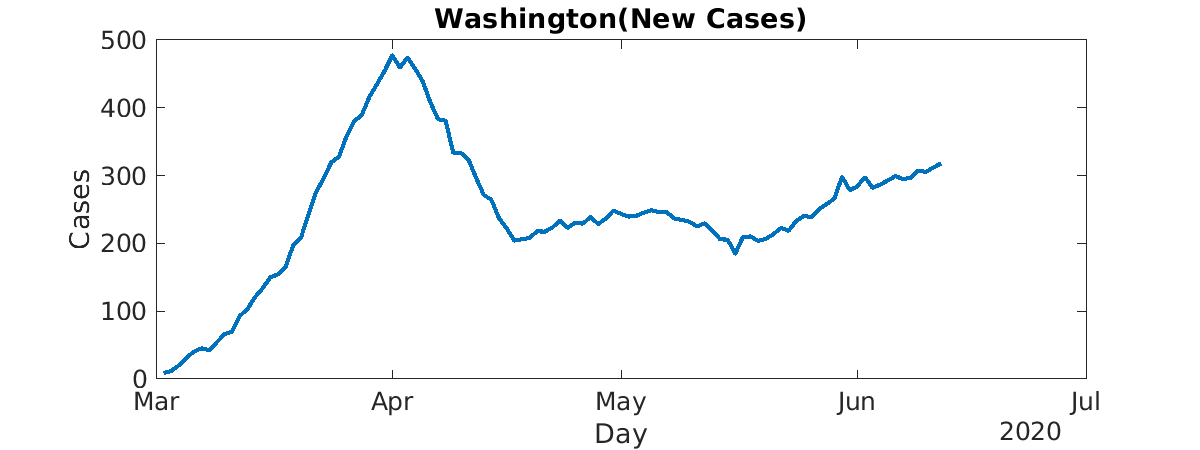

sel_reg = "New York City"; % Select a region to predict

 

xx = find(strcmpi(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx;
end

figure('DefaultAxesFontSize',18);
offset = 40;
trueshow = (offset:size(data_4_s, 2));
Tx = datetime(2020, 1, 21)+ caldays(trueshow);
plot(Tx(2:end), diff(data_4_s(cid, offset:end)), 'LineWidth', 3);

title([countries{cid} '(New Cases)'])
xlabel('Day');
ylabel('Cases');
set(gcf,'position',[10,10,1200,450])
%legend({'True', 'S', 'NL(i)', 'NL(f)', 'F'}, 'Location','northeast', 'Interpreter', 'latex');
hold off;

## Auto detect unreported from intial betas (incremental, full, fixed)

un_data = cell(length(popu), 1);
un_prob_f = zeros(length(popu), 1);
un_prob_i = zeros(length(popu), 1);
un_prob_ll = zeros(length(popu), 1);
ci_i = cell(length(popu), 1);
ci_ll = cell(length(popu), 1);
ci_f = cell(length(popu), 1);

del = zeros(length(popu), 1);
eps_f = zeros(length(popu), 1);

infec_un0_f = zeros(length(popu), horizon);
infec_un0_i = zeros(length(popu), horizon);
infec_un0_ll = zeros(length(popu), horizon);

for j=1:length(popu)
    
    alpha = 1; %best_param_list_no(j, 3)*0.1;
    k = 1; %best_param_list_no(j, 1);
    jp = 7; %best_param_list_no(j, 2);
    beta_notravel = {[0.5; 0]};
    
    del3 = 0.3;
    a_T = data_4_s(j, end)/popu(j);
    
    [beta_cell(j), un_prob_f(j), eps_f(j), initdat, ci_f(j), del(j)] = learn_un_fix_beta(data_4_s(j, start_time-k*jp:end), popu(j), k, jp, alpha, a_T, 7, 'l');  
    infec_un0_f(j, :) = var_simulate_pred_un(initdat, 0, beta_cell(j), popu(j), k, horizon, jp, 1./un_prob_f(j));
    [peak_test] = unreported_reliability_test(data_4_s(j, start_time-k*jp:end), popu(j), un_prob_f(j), beta_cell{j}, del3, jp);
    if peak_test < 0
        disp(['F for ' countries{j} ' failed peak_test']);
    end
    if del(j) >=1
        disp(['F for ' countries{j} ' failed del_test']);
    end
    
       
    [beta_auto_un1(j), un_prob_i(j), init_dat(j, :), fittedC, ci_i(j)] = learn_nonlin(data_4_s(j, T_tr-k*jp:T_tr+T_val), popu(j), k, jp, 1, beta_notravel, 'i');
    infec_un0_i(j, :) = var_simulate_pred_un(init_dat(j, :), 0, beta_auto_un1(j), popu(j), k, horizon, jp, 1./un_prob_i(j));
    
    [peak_test] = unreported_reliability_test(data_4_s(j, T_tr-k*jp:T_tr+T_val), popu(j), un_prob_i(j), beta_auto_un1{j}, del3, jp);
    if peak_test < 0
        disp(['NL(i) for ' countries{j} ' failed peak test']);
    end
       
    [beta_auto_un2(j), un_prob_ll(j), init_dat(j, :), fittedC(j), ci_ll(j)] = learn_nonlin(data_4_s(j, T_tr-k*jp:T_tr+T_val), popu(j), k, jp, 1, beta_notravel, 'l');
    infec_un0_ll(j, :) = var_simulate_pred_un(init_dat(j, :), 0, beta_auto_un2(j), popu(j), k, horizon, jp, 1./un_prob_ll(j));
    [peak_test] = unreported_reliability_test(data_4_s(j, T_tr-k*jp:T_tr+T_val), popu(j), un_prob_ll(j), beta_auto_un2{j}, del3, jp);
    if peak_test < 0
        disp(['NL(f) for ' countries{j} ' failed peak test']);
    end
    
end

F for California failed peak_test


NL(i) for California failed peak test


NL(f) for California failed peak test


F for Arizona failed peak_test


NL(i) for Arizona failed peak test


NL(f) for Arizona failed peak test


NL(i) for Wisconsin failed peak test


NL(f) for Wisconsin failed peak test


F for Texas failed peak_test


NL(i) for Texas failed peak test


NL(f) for Texas failed peak test


F for Utah failed peak_test


NL(i) for Utah failed peak test


NL(f) for Utah failed peak test


F for Oregon failed peak_test
F for Florida failed peak_test
F for North Carolina failed peak_test


NL(i) for North Carolina failed peak test


NL(f) for North Carolina failed peak test


F for Nevada failed peak_test
F for Tennessee failed peak_test
F for Kentucky failed peak_test
F for Oklahoma failed peak_test
F for South Carolina failed peak_test


NL(i) for South Carolina failed peak test


NL(f) for South Carolina failed peak test


NL(i) for Virginia failed peak test


NL(f) for Virginia failed peak test


F for Arkansas failed peak_test


NL(i) for Arkansas failed peak test


NL(f) for Arkansas failed peak test


F for Mississippi failed peak_test


NL(i) for Mississippi failed peak test


NL(f) for Mississippi failed peak test


F for Alaska failed peak_test


NL(i) for Maine failed peak test


NL(f) for Maine failed peak test


F for Alabama failed peak_test


NL(i) for Alabama failed peak test


NL(f) for Alabama failed peak test


F for Puerto Rico failed peak_test


NL(i) for Puerto Rico failed peak test


NL(f) for Puerto Rico failed peak test


## Generate table for unreported cases

We have assumed that the dynamics don't change in the time period under consideration.  We do not provide any tests to confirm this. For now, this has to be assessed visually.



delim = ' & ';
endline = '\\';
res_i = {}; res_ll = {}; res_f = {};
for j=1:length(popu)
    if ~isreal(del(j))
        continue;
    end
    res_i{j} =  [num2str(1./(ci_i{j}(1, 2))),' - ' , num2str(1./(un_prob_i(j))),' - ',  num2str(1./(ci_i{j}(1, 1)))];   
    res_ll{j} = [num2str(1./(ci_ll{j}(1, 2))),' - ' , num2str(1./(un_prob_ll(j))),' - ', num2str(1./(ci_ll{j}(1, 1)))];   
    res_f{j} = [num2str(1./(ci_f{j}(1, 2))),' - ' , num2str(1./(un_prob_f(j))),' - ', num2str(1./((1-del(j))*ci_f{j}(1, 1)))];   
    disp([countries{j}, delim, res_i{j}, delim, res_ll{j}, delim res_f{j}, endline]);   
end

Illinois & 30.3602 - 33.4322 - 37.1959 & 31.9536 - 33.4813 - 35.1624 & 36.3089 - 36.819 - 40.8824\\
California & 0.062696 - 1 - -0.071684 & 0.10018 - 1 - -0.12528 & 38.5751 - 41.062 - 49.266\\
Arizona & 0.023536 - 1 - -0.024699 & 0.048725 - 1 - -0.053986 & 0.16096 - 1 - -0.12132\\
Massachusetts & 24.1917 - 27.3885 - 31.5589 & 25.4437 - 27.5206 - 29.9668 & 30.3476 - 31.5003 - 38.2333\\
Wisconsin & 15.4828 - 26.6966 - 96.8244 & 18.1519 - 25.268 - 41.5615 & 5.4894 - 7.8559 - 13.6251\\
Texas & 10.9511 - 24.8484 - -92.3636 & 21.5579 - 32.0228 - 62.2322 & 119.0208 - 128.3729 - 157.9401\\
Nebraska & 43.7911 - 52.5038 - 65.5444 & 52.066 - 58.2282 - 66.0449 & 62.5201 - 66.1797 - 71.3027\\
Utah & 0.036519 - 1 - -0.039396 & 0.065675 - 1 - -0.075605 & 2.0149 - 3.944 - 81.349\\
Oregon & 51.5848 - 97.0714 - 821.1171 & 63.8193 - 94.6126 - 182.8284 & 74.3177 - 84.7141 - 143.871\\
Florida & 0.025563 - 1 - -0.02694 & 0.035882 - 1 - -0.038656 & 72.3766 - 80.5757 - 124.9215\\
Rhode Island & 27.2846 - 31.0

## Plot comparison for selected region

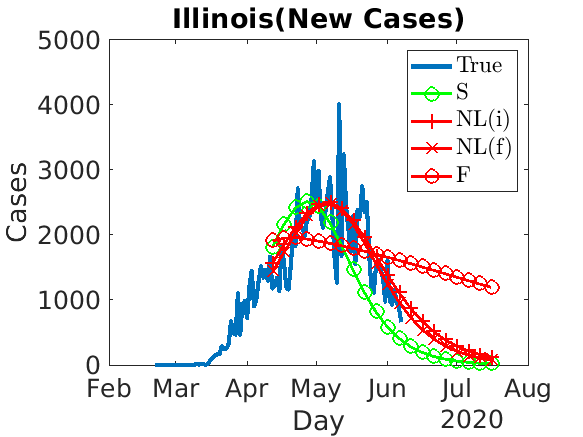

figure('DefaultAxesFontSize',18);
sel_reg = "illinois"; % Select a region to predict

 

xx = find(strcmpi(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx;
end

%T_tr = Final_list{cid, 1};
T_tr = start_time;
offset = 30;
trueshow = (offset:size(data_4_s, 2));
Tx = datetime(2020, 1, 21)+ caldays(trueshow);
plot(Tx(2:end), diff(data_4_s1(cid, offset:end)), 'LineWidth', 3);
hold on;

Tx = datetime(2020, 1, 21)+caldays(start_time+1:start_time+size(infec_un, 2));
%Tx_sd = datetime(2020, 1, 21)+caldays(sd_start+1:sd_start+size(infec_un0_i, 2));

yy = diff(infec_un(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); hold on;
yy = diff(infec_un0_i(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'r', 'Marker', '+', 'LineWidth', 2, 'MarkerSize', 10, 'LineStyle', '-'); hold on;
yy = diff(infec_un0_ll(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'r', 'Marker', 'x', 'LineWidth', 2, 'MarkerSize', 10); hold on;
yy = diff(infec_un0_f(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'r', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); hold on;

title([countries{cid} '(New Cases)'])
xlabel('Day');
ylabel('Cases');
legend({'True', 'S', 'NL(i)', 'NL(f)', 'F'}, 'Location','northeast', 'Interpreter', 'latex');
hold off;

## Generate plots for all regions

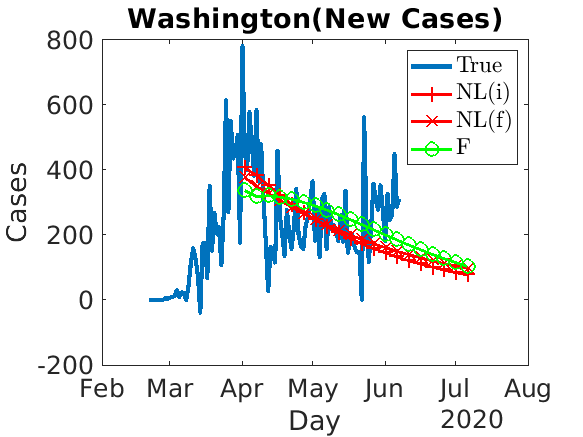

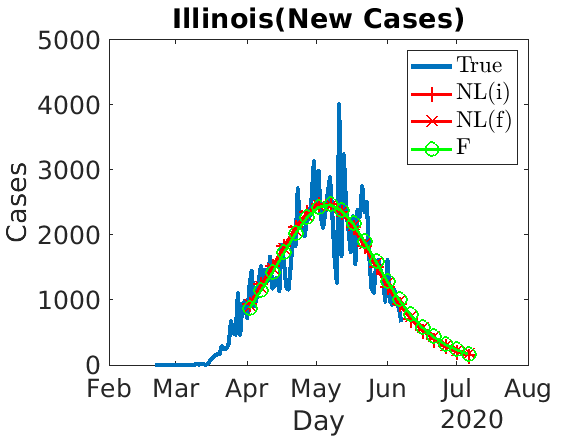

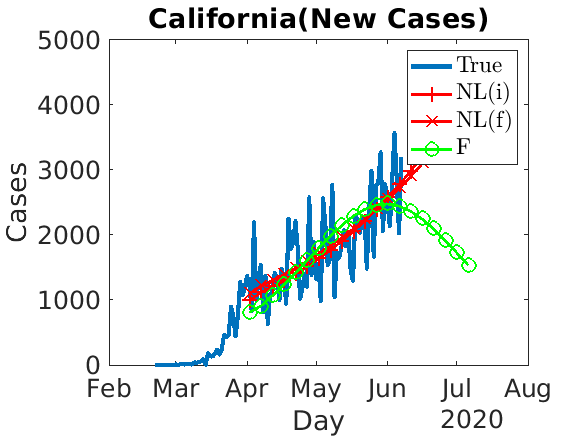

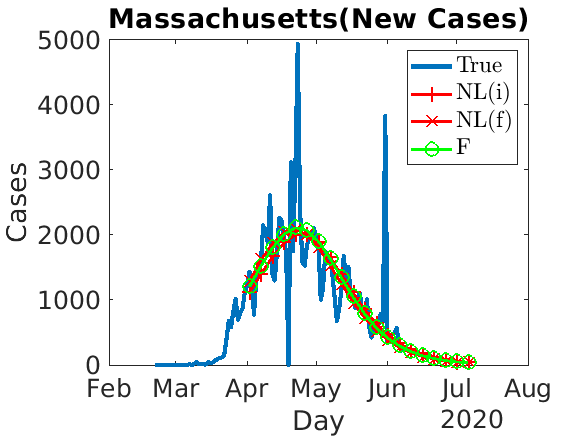

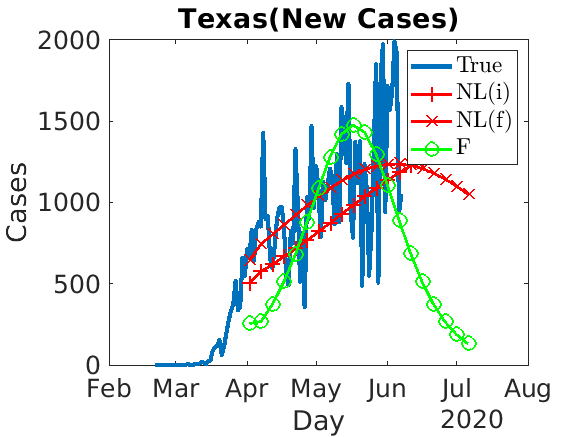

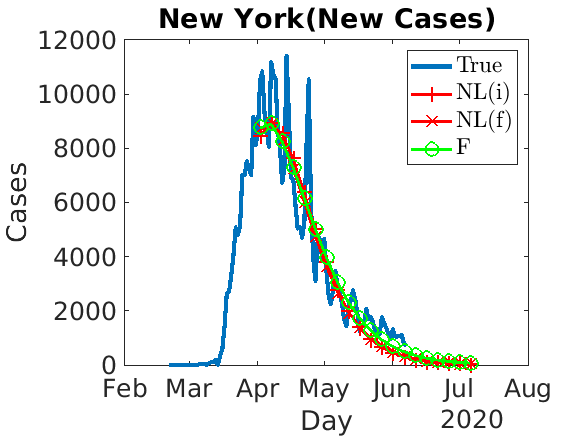

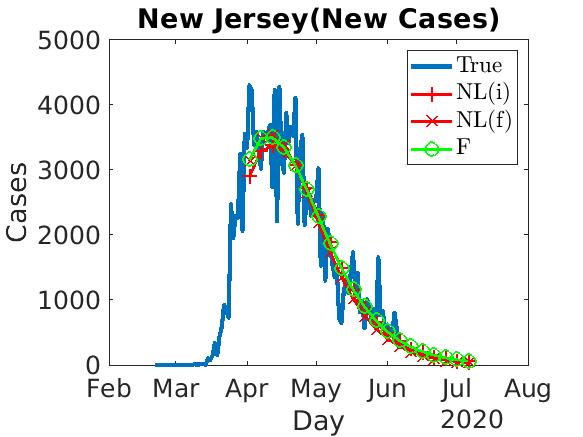


for cid = 1: length(countries)
    %subplot(length(countries), 1, cid);
    figure('DefaultAxesFontSize',18);
    
    offset = 30;
    trueshow = (offset:size(data_4_s, 2));
    Tx = datetime(2020, 1, 21)+ caldays(trueshow);
    plot(Tx(2:end), diff(data_4_s1(cid, offset:end)), 'LineWidth', 3);
    hold on;
    
    Tx = datetime(2020, 1, 21)+caldays(T_tr+1:T_tr+size(infec_un, 2));
    Tx_sd = datetime(2020, 1, 21)+caldays(sd_start+1:sd_start+size(infec_un0_i, 2));
    
%    yy = diff(infec_un(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); hold on;
    yy = diff(infec_un0_i(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'r', 'Marker', '+', 'LineWidth', 2, 'MarkerSize', 10, 'LineStyle', '-'); hold on;
    yy = diff(infec_un0_ll(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'r', 'Marker', 'x', 'LineWidth', 2, 'MarkerSize', 10); hold on;
    yy = diff(infec_un0_f(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); hold on;
    
    title([countries{cid} '(New Cases)'])
    xlabel('Day');
    ylabel('Cases');
    legend({'True', 'NL(i)', 'NL(f)', 'F'}, 'Location','northeast', 'Interpreter', 'latex');
    hold off;
    
end